# Based on David Heeger's lecture notes: "The Membrane Equation"

RC circuit stands for a circuit that consists of a capacitor and a resistor.

Capacitor: charges that are stored per unit pressure (?). In the water-balloon example, this can be seen as representing the elasticity of the balloon. 

Resistor: how easy the charges pass. In the water-balloon example, resistor can be seen as the size of holes on the balloon

There are two ways of representing the net current in and out of the balloon (or two ways representing net current in and out of the circuit)

## An RC model of a passive neural membrane

## The first way: through pressure difference and conductance

Vm  = 5; % membrane potential, voltage inside the membrane? In unit of Volt
E   = 3; % battery, voltage outside the membrane? In unit of Volt
g   = 1; % conductance, increases if the holes are made big. In unit of siemens or 1/ohm
Ig  = g * (Vm - E); % current, in unit of Volt/ohm = amp

% Ig, the outward current increases with conductance (hole size), internal pressure/potential, and decreases with external potential/pressure.


## The second way: through rate of pressure change and capacitance

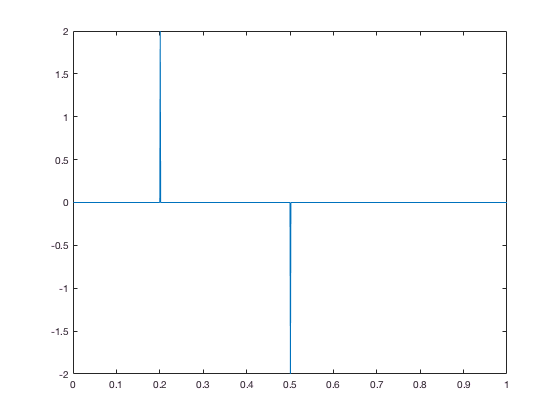

% q  = 1;  1 unit of charge
% Vm = 5;  membrane potential, in unit of Volt

C = 2; %  capacitance,q/Vm, in unit of charge per Volt

t = 0.001 : 0.001 : 1;

Vm_t = zeros(1, length(t));
Vm_t(t > 0.2 &  t <= 0.5) = 1;

dVm_t = diff(Vm_t);

Ig_t = []; Ig_t(1) = 0;

for k = 2 : length(t)
    Ig_t(k) = C * dVm_t(k - 1);
end

figure (1), clf
plot(t, Ig_t)